# Report

by: ardimas (ardimasandipurwita@outlook.com)

19 Aug 2019

clear 

addpath('./../../lib/filter')
addpath('./../../lib/misc')
addpath('./../../lib/simulator')
addpath('./../../lib/tgbb')
addpath('./../../data/freqresponse')

## Main Results

Comparison between mine and what's been published on [https://mentor.ieee.org/802.11/dcn/19/11-19-1224-01-00bb-simulation-results-for-802-11a-phy-in-lc.ppt.](https://mentor.ieee.org/802.11/dcn/19/11-19-1224-01-00bb-simulation-results-for-802-11a-phy-in-lc.ppt.) 

Note that I run the payload (L-SIG+PSDU) simulations using the NHT waveforms (802.11a).

% openfig('PERvsEbN0_MCS0_NHT_updatedSNRdefinition.fig','visible')


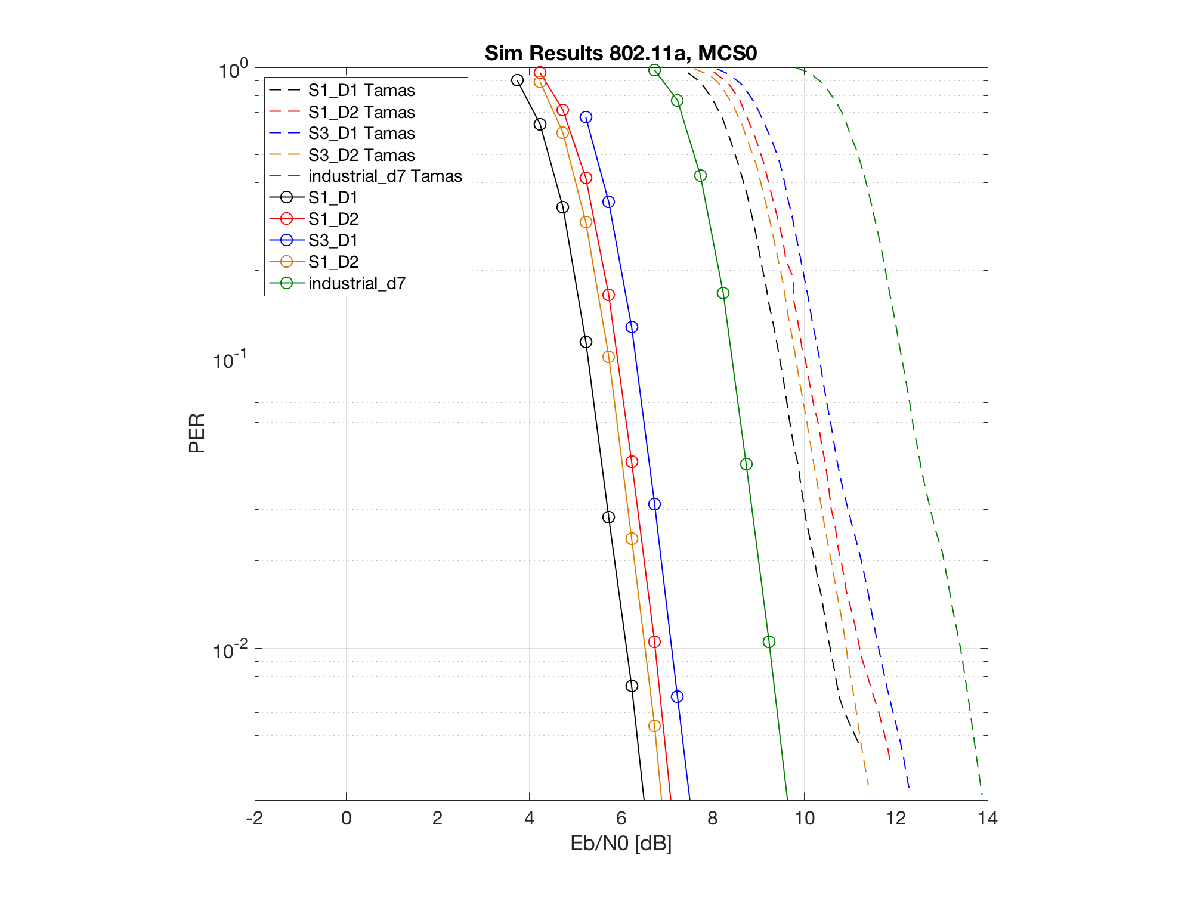

Why are they different? The main reason is probably due to the AFEs' models that are used. 

% open difference_in_afe.fig

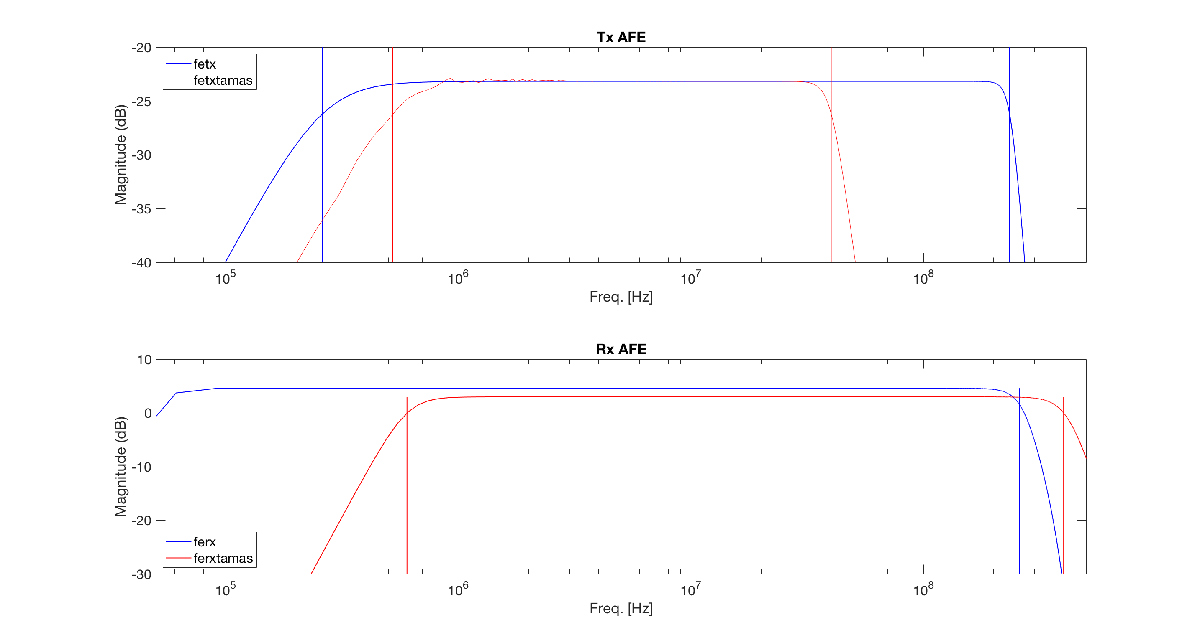

Note that there is approximately 3dB difference between our Rx AFE implementations. 

Other minor differents are:

- the use of windowed OFDM waveform,

- upsampling implementation (I'm using pulse shaping root raised cosine and matched filter),

- DC bias and AGC implementations.

## Simulation Setups

My simulation setups can be seen in the mat files.

ls *.mat

PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S1D1_beta01.mat
PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S1D2_beta01.mat
PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S3D1_beta01.mat
PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S3D2_beta01.mat
PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_industriald7_beta01.mat



load PERvsSNR_NHT_BW20_PSDU1000_MCS0_SPS50_S1D1_beta01.mat
whos

  Name                  Size            Bytes  Class     Attributes

  SamplesPerSymbol      1x1                 8  double              
  cfgNHT                6x1                24  uint32              
  maxNumErrors          1x1                 8  double              
  maxNumPackets         1x1                 8  double              
  packetErrorRate       1x9                72  double              
  snr                   1x9                72  double              
  whichCase             1x5                10  char                



- PSDU length=1000

- MCS= 0

- Channel bandwidth= 20 MHz

- Case= 'S1_D1'

- SamplesPerSymbol=50 (1 Gsamples/sec)

PER curves can be plotted as follows.

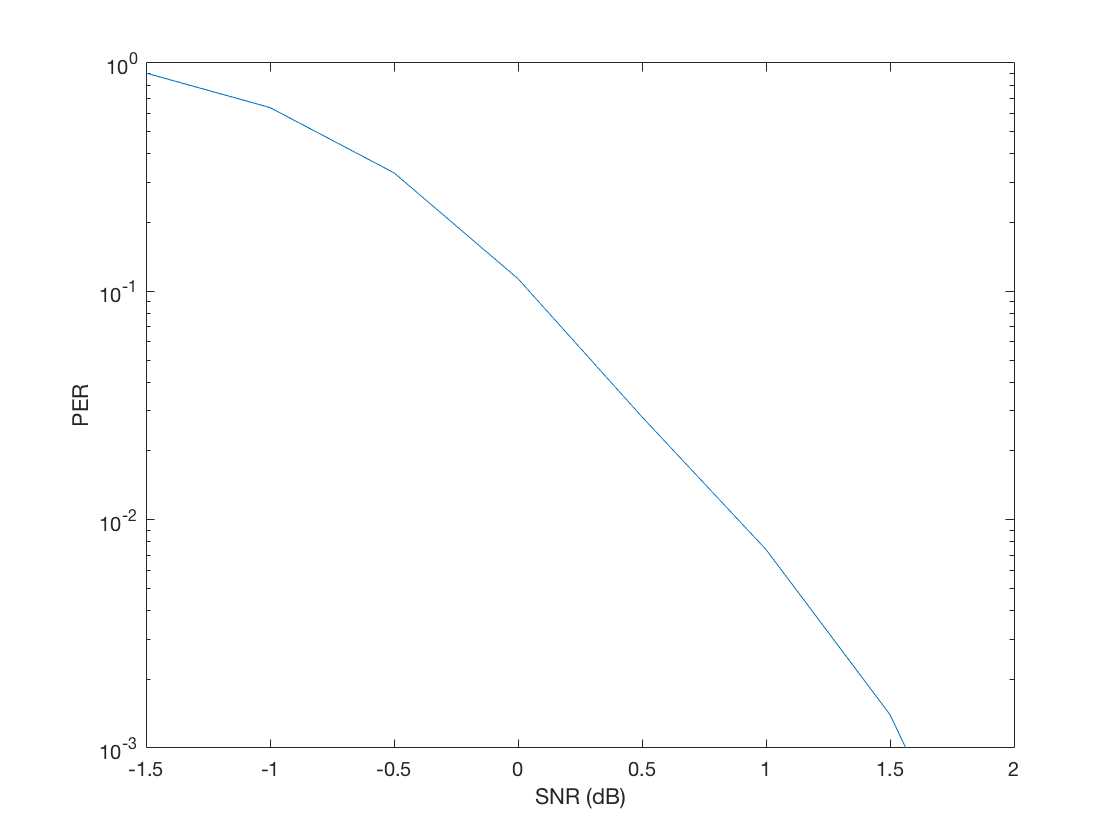

semilogy(snr,packetErrorRate)
ylim([1e-3,1])
ylabel('PER')
xlabel('SNR (dB)')

The conversion of SNR to EbN0 follows the below equation.


$$\frac{E_\text{b}}{N_0} = \text{SNR} \frac{\text{BW}}{R_\text{b}}$$


where BW is the bandwidth and $R_\text{b}$is the data rate (from the MCS table). In this case, BW = 20 MHz and $R_\text{b} = 6 \text{Mbps}.$ So,


$$\frac{E_\text{b}}{N_0} (\text{dB}) = \text{SNR} (\text{dB}) + 5.23\ \text{dB}$$


## Remarks

I still have doubts about the effect of defining SNR in the optical domain to the conversion from SNR to EbN0.

Recall the below system diagram from [https://mentor.ieee.org/802.11/dcn/19/11-19-0187-04-00bb-evaluation-methodology-for-phy-and-mac-proposals.docx.](https://mentor.ieee.org/802.11/dcn/19/11-19-0187-04-00bb-evaluation-methodology-for-phy-and-mac-proposals.docx.) Note that the noise is injected in the optical domain, and the SNR is defined in the optical domain as well.

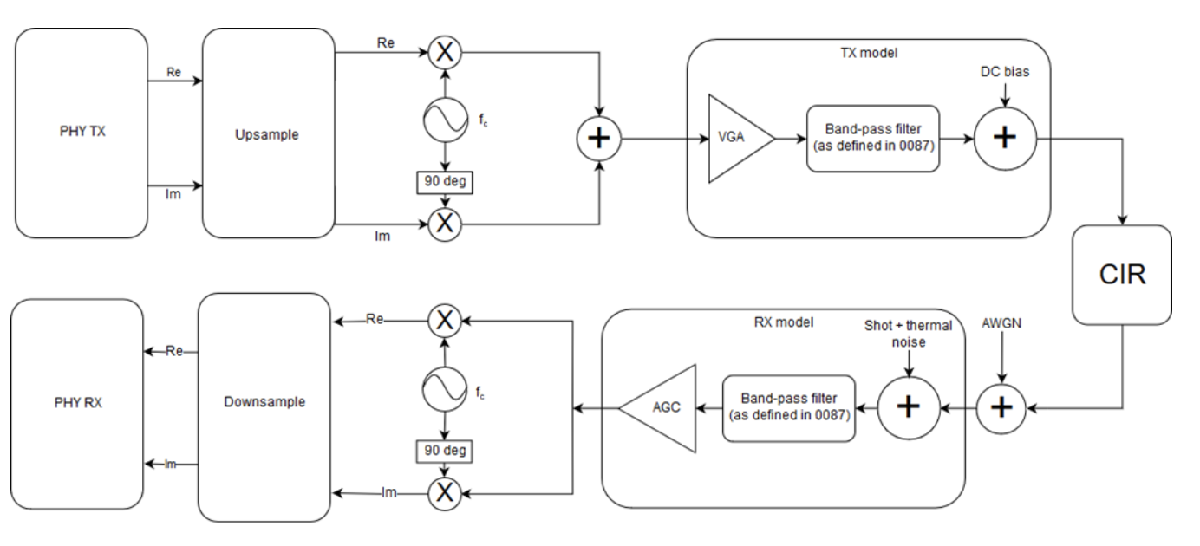

Then, I want to validate whether the power of the signal and noise in the SNR term are scaled equally. Apparently, it is not the case. See the below figure. Here I use Tamas' code due to the preparation if it's required for me to discuss with Tamas in the future. 

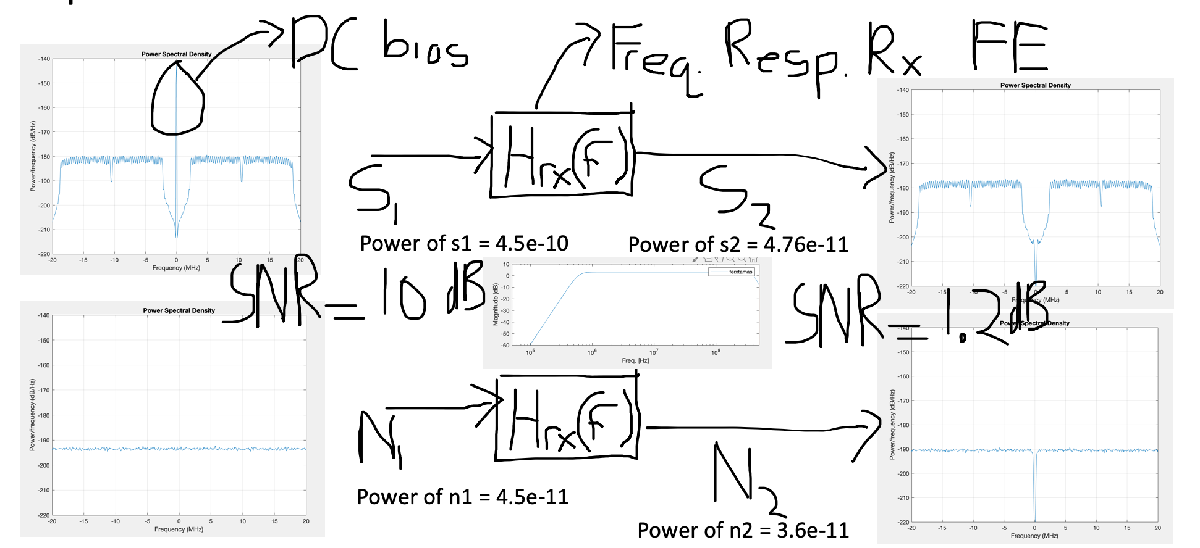

Note that the majority of the power of the signal is lost due to the highpass cutoff of the Rx AFE. 

In the end, I still need to double check my arguments here with the others if there's any mistake.